% 5.15 7
clear;

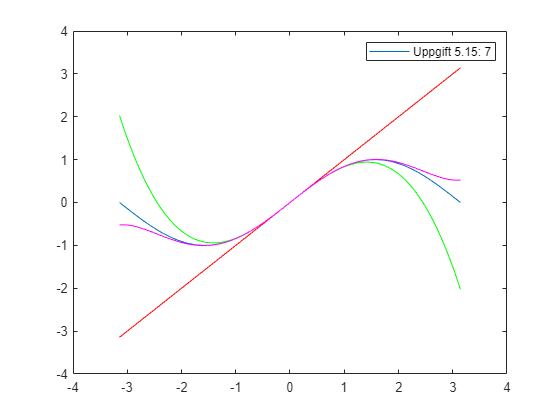

x = linspace(-pi, pi);
ySin = sin(x);
y1 = x;
y3 = x - (x.^3)/6;
y5 = y3 + (x.^5)/120;

plot(x,ySin)
hold on;
plot(x,y1,'-r');
plot(x,y3,'-g');
plot(x,y5,'-m');
legend("Uppgift 5.15: 7");

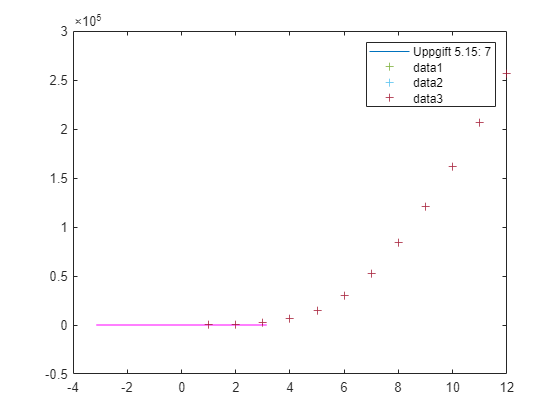

% 5.15 8 a
clear;
t = linspace(1,12,12);
N = [97 709 2698 6928 15242 29944 52902 83903 120612 161711 206247 257085];

plot(t,N,'+');
semilogy(t,N,'+');
loglog(t,N,'+');

% 5.15 8 b
clear;
t = [0 2 4 6 8 10 12 14];
N = [2 5 10 20 40 109 200 403]

N =      2     5    10    20    40   109   200   403


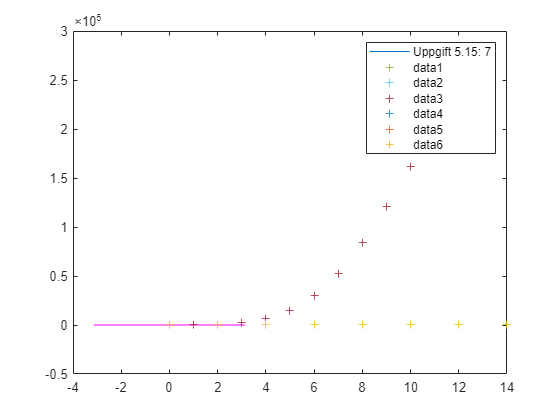

plot(t,N,'+');
semilogy(t,N,'+');
loglog(t,N,'+');

% 5.15 16
clear;
z = linspace(-50,50);
pA = z.^5 - 1.1;
pB = z.^2+3*z+4;
pC = z.^2+(-1+1i)*z+2-2i;

plot(z, pA);
hold on;
plot(z, pB);
plot(z, pC);

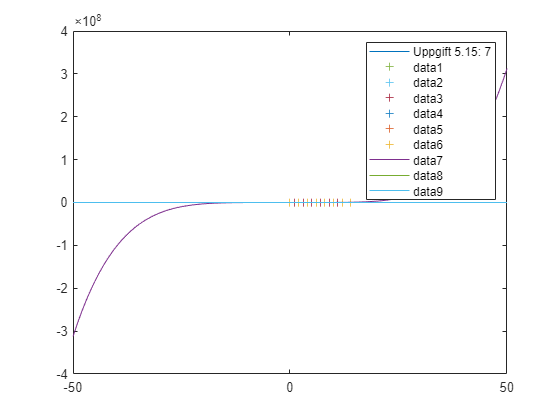

hold off;

[MinA, IndexA] = min(abs(pA))

MinA = 1.0671

IndexA = 51

[MinB, IndexB] = min(abs(pB))

MinB = 1.7502

IndexB = 49

[MinC, IndexC] = min(abs(pC))

MinC = 2.3016

IndexC = 51

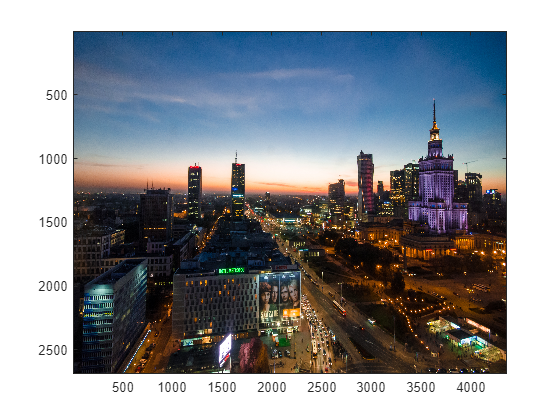

% 5.15 19
clear;
%[url_img, map] = imread('https://static.pexels.com/photos/14621/Warsaw-at-night-free-license-CC0.jpg');
A = imread('https://static.pexels.com/photos/14621/Warsaw-at-night-free-license-CC0.jpg');
%figure, imshow(url_img), title('Image from url')
imagesc(A);

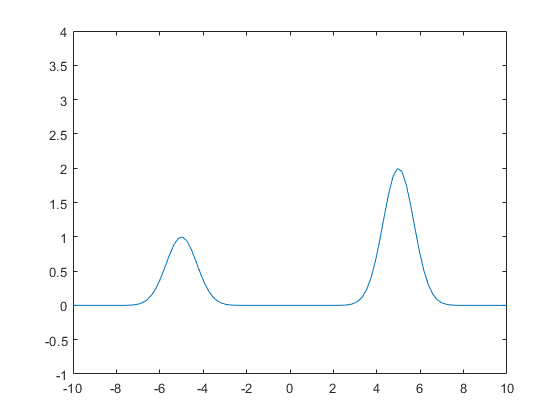

% 5.15 21
clear
x = linspace(-10,10);

f1 = @(x) exp(-(x+5).^2);
f2 = @(x) 2*exp(-(x-5).^2);

plot(x, f1(x) + f2(x))
axis([-10 10 -1 4])

frames = moviein(101);

for i = 1:101
    t = 0.1*(i-1);
    plot(x, f1(x-t) + f2(x+t));
    axis([-10 10 -1 4])
    frames(:,i) = getframe;
end    
movie(frames, 10)
vidObj = VideoWriter('animering.avi');
open(vidObj);
writeVideo(vidObj,frames);
close();


% 6.18 9
clear
x = input('Input your x: ')

x = 5

y = input('Input your y: ')

y = 6


v = [x, y];

if x == 0 && y > 0
    ang = pi/2;
elseif x == 0 && y < 0
    ang = -pi/2
elseif x > 0
    ang = atan(y/x);
elseif x < 0 || y >= 0
    ang = atan(y/x) + pi;
elseif x < 0 || y <= 0
    ang = atan(y/x) - pi;
end
ang

ang = 0.8761

angle(x+i*y)

ans = 0.8761

% 6.18 14
clear
f0 = 0;
f1 = 1;
fRes = f0 + f1;
counter = 2;
while fRes < 100000
    f0 = f1;
    f1 = fRes;
    fRes = f0 + f1;
    counter = counter+1;
end
counter

counter = 26

fRes

fRes = 121393

% 6.18 27 a
clear
v = [1 -2 -3 -4 2 3 4]

v =      1    -2    -3    -4     2     3     4


minsta = 1e30;
n = length(v);
for i = 1:n
    if v(i) < minsta
        minsta = v(i);
        pos = i;
    end
end
disp('Minsta värde'), disp(minsta)

Minsta värde
    -4



disp('Position'), disp(pos)

Position
     4



% 6.18 27 b
clear
v = [1 -2 -3 -4 2 3 4]

v =      1    -2    -3    -4     2     3     4


storsta = 1e-30;
n = length(v);
for i = 1:n
    if v(i) > storsta
        storsta = v(i);
        pos = i;
    end
end
disp('Storsta värde'), disp(storsta)

Storsta värde
     4



disp('Position'), disp(pos)

Position
     7



% 6.18 27 c
clear
n = input('Input your rows: ')

n = 3

m = input('Input your columness: ')

m = 3

v = rand(n, m)

v =     0.8147    0.9134    0.2785
    0.9058    0.6324    0.5469
    0.1270    0.0975    0.9575


minsta = 1e30;
for i = 1:n %rows
    for j = 1:m %cols
        if v(i, j) < minsta
            minsta = v(i, j);
            pos = [i, j];
        end
    end
end
disp('Minsta värde'), disp(minsta)

Minsta värde
    0.0975



disp('Position'), disp(pos)

Position
     3     2



% 6.18 27 d
clear
n = input('Input your rows: ')

n = 7

m = input('Input your columness: ')

m = 4

d = input('Input your depth: ')

d = 4

v = rand(n, m, d)

v = v(:,:,1) =

    0.9649    0.4218    0.9340    0.7060
    0.1576    0.9157    0.6787    0.0318
    0.9706    0.7922    0.7577    0.2769
    0.9572    0.9595    0.7431    0.0462
    0.4854    0.6557    0.3922    0.0971
    0.8003    0.0357    0.6555    0.8235
    0.1419    0.8491    0.1712    0.6948


v(:,:,2) =

    0.3171    0.1869    0.6797    0.5853
    0.9502    0.4898    0.6551    0.2238
    0.0344    0.4456    0.1626    0.7513
    0.4387    0.6463    0.1190    0.2551
    0.3816    0.7094    0.4984    0.5060
    0.7655    0.7547    0.9597    0.6991
    0.7952    0.2760    0.3404    0.8909


v(:,:,3) =

    0.9593    0.8143    0.4733    0.7572
    0.5472    0.2435    0.3517    0.7537
    0.1386    0.9293    0.8308    0.3804
    0.1493    0.3500    0.5853    0.5678
    0.2575    0.1966    0.5497    0.0759
    0.8407    0.2511    0.9172    0.0540
    0.2543    0.6160    0.2858    0.5308


v(:,:,4) =

    0.7792    0.1622    0.6541    0.1524
    0.9340    0.7943    0.6892    0.8258

minsta = 1e30;
for i = 1:n %rows
    for j = 1:m %cols
        for k = 1:d
            if v(i, j, k) < minsta
                minsta = v(i, j, k);
                pos = [i, j, k];
            end
        end
    end
end
disp('Minsta värde'), disp(minsta)

Minsta värde
    0.0119



disp('Position'), disp(pos)

Position
     6     1     4

